# German Traffic Sign Classification using Alexnet

tic
clc
path(path,genpath(cd));
format compact;close all;
disp('You are all set to go :)');

You are all set to go :)


## Loading the Dataset

DatasetPath = fullfile(cd,'German Traffic sign images','Train');
imds = imageDatastore(DatasetPath, ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');

## Splitting into training and validation set

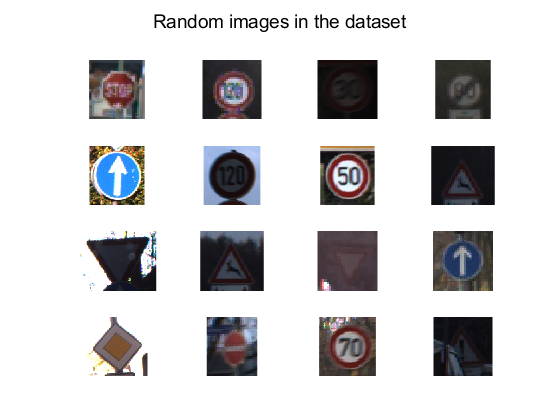

[imdsTrain,imdsValidation] = splitEachLabel(imds,0.7,'randomized');
numTrainImages = numel(imdsTrain.Labels);
idx = randperm(numTrainImages,16);
figure
for i = 1:16
    subplot(4,4,i)
    I = readimage(imdsTrain,idx(i));
    imshow(I)    
end
suptitle("Random images in the dataset")

## Initializing Alexnet

net = alexnet;
%analyzeNetwork(net)
inputSize = net.Layers(1).InputSize 

inputSize =    227   227     3


layersTransfer = net.Layers(1:end-3);
numClasses = numel(categories(imdsTrain.Labels));
layers = [
    layersTransfer
    fullyConnectedLayer(numClasses,'WeightLearnRateFactor',20,'BiasLearnRateFactor',20)
    softmaxLayer
    classificationLayer];

## Training the network

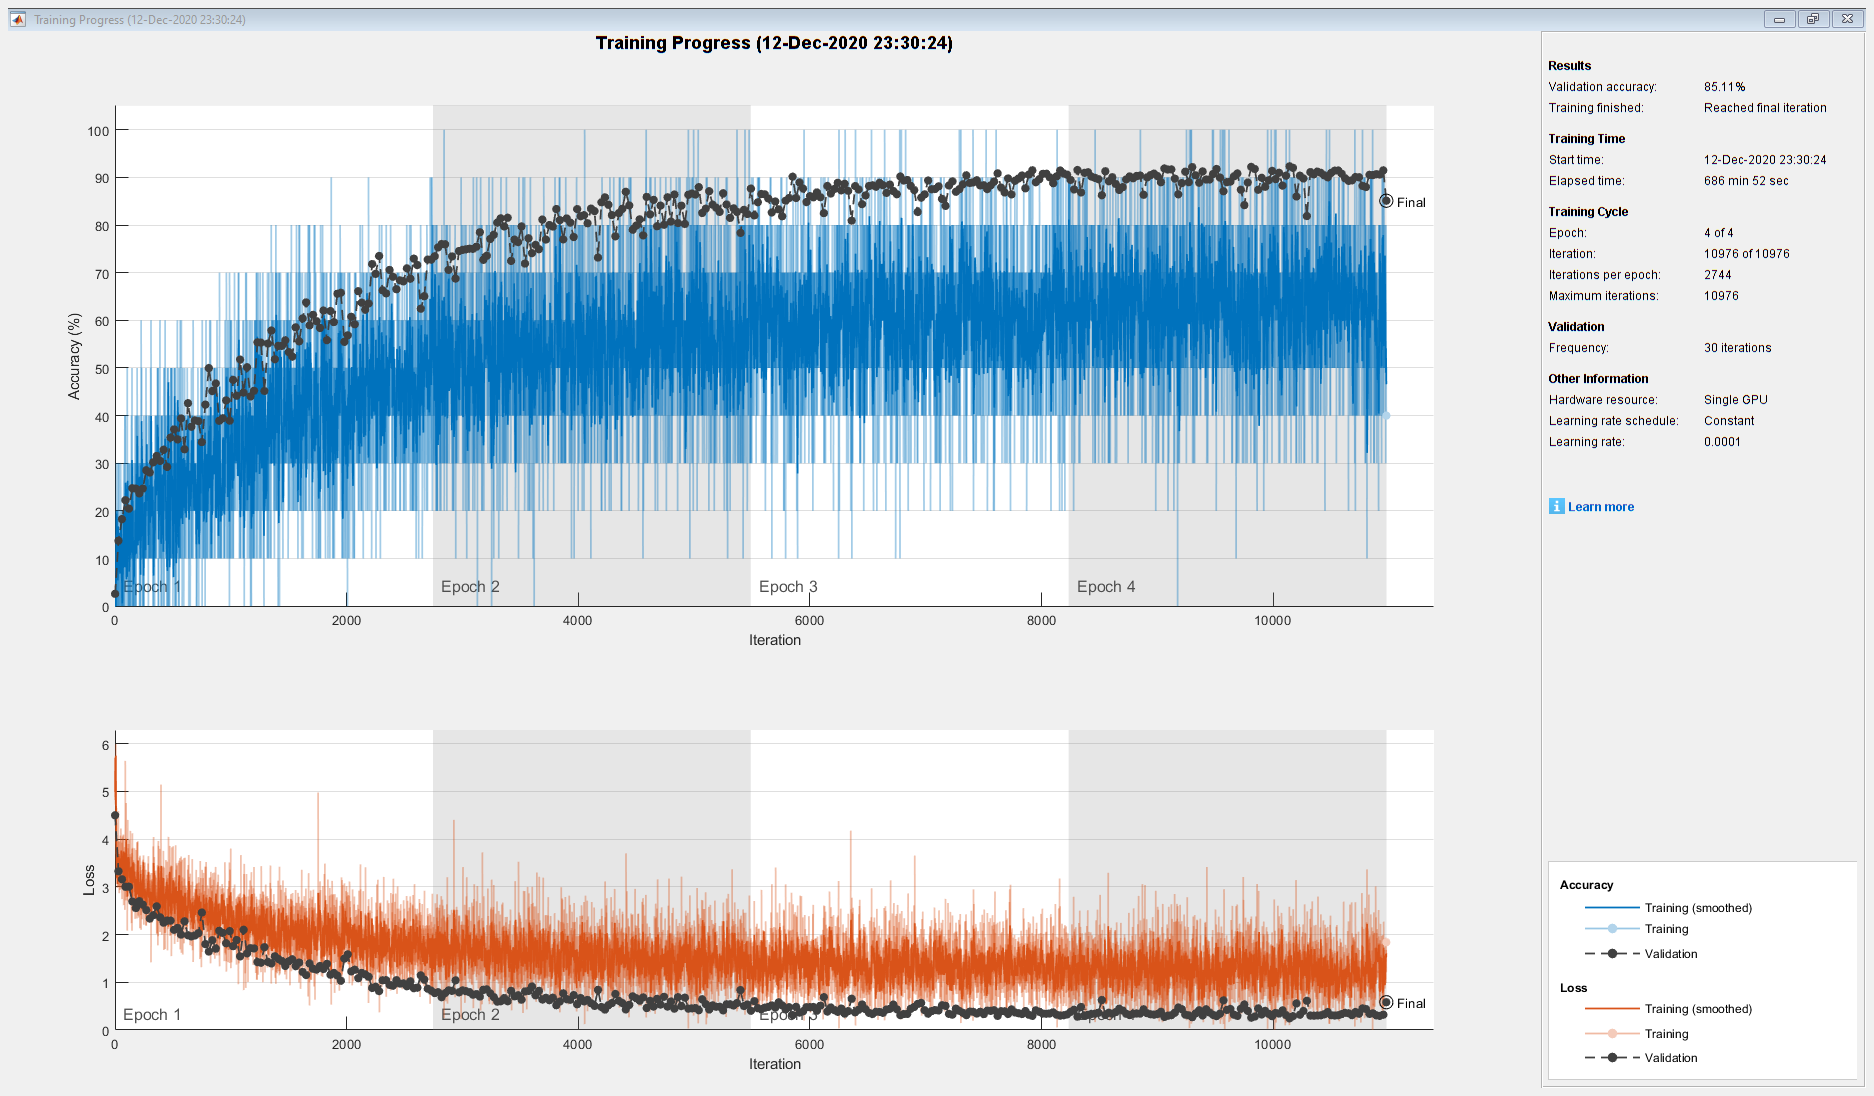

pixelRange = [-30 30];
imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange);
augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain, ...
    'DataAugmentation',imageAugmenter);

augimdsValidation = augmentedImageDatastore(inputSize(1:2),imdsValidation);

options = trainingOptions('adam', ...
    'MiniBatchSize',10, ...
    'MaxEpochs',4, ...
    'InitialLearnRate',1e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augimdsValidation, ...
    'ValidationFrequency',30, ...
    'Verbose',false, ...
    'Plots','training-progress');

netTransfer = trainNetwork(augimdsTrain,layers,options);

## Classifying Validation dataset

[YPred,scores] = classify(netTransfer,augimdsValidation);

## Classify test dataset

test_DatasetPath = fullfile(cd,'German Traffic sign images','Test');
test_imds = imageDatastore(test_DatasetPath, ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');

augimdstest = augmentedImageDatastore(inputSize(1:2),test_imds);
[Y_test,scores_test] = classify(netTransfer,augimdstest);

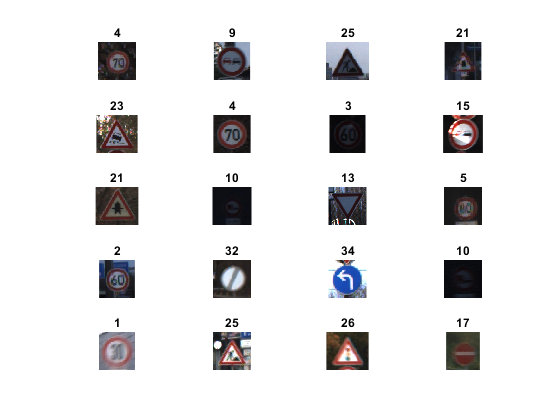

idx = randperm(numel(test_imds.Files),20);
figure
for i = 1:20
    subplot(5,4,i)
    I = readimage(test_imds,idx(i));
    imshow(I)
    label = Y_test(idx(i));
    title(string(label));
end